# Ajustement des paramètres de collision

## Fonction de probabilité de collision $p(\Delta z)$

On définir la probabitlité $p$ de collision entre deux particules comme une fonction de la distance $\Delta z$ entre les deux particules. On doit avoir :

- 
$$p(0) = max(p(\Delta z))$$


- 
$$p\left(\|\Delta z\| = \frac{d_1+d_2}{2}\right) = 1$$


- 
$$p\left(\|\Delta z\| \to \delta_{max} + \frac{d_1+d_2}{2}\right) \to 0$$


- 
$$p\left(\|\Delta z\| > \delta_{max} + \frac{d_1+d_2}{2}\right) < 0$$


Il faut donc une fonction paire ($f(-x)=f(x)$) , décroissante sur $[0,\infty]$.

On choisit une fonction $p$ Gaussienne :


$$p(\Delta z) = ae^{-\frac{(\Delta z+b)^2}{2c^2}}+d$$


- $a$ : hauteur du pic, $a>1$

- $b$ : position du pic, $b=0$

- $c$ : équart type, inconnu

- $d$ : translation verticale de la courbe, $d<0$

En fixant $c$ on obtient :


$$\begin{cases} {p\left(\frac{d1+d2}{2}\right)=1}&{}\\ {p\left(\delta_{max}+\frac{d1+d2}{2}\right)=0}&{}\\ \end{cases} \Rightarrow \begin{cases} {a\,=\left(1-d\right)e^{\frac{\left(\frac{d1+d2}{2}\right)^{2}}{2c²}}}&{}\\ {\frac{1}{d}\,=1-e^{\frac{\delta_{max}^{2}+\delta_{max}\left(d1+d2\right)}{2c²}}}&{}\\ \end{cases}$$


On va donc chercher à calibrer $c$ par rapport à des données de collision pour un pas de temps $dt \leq dt_{max}$.

## Obtention des données de collision

$z(t-dt)$ est retenu pour chaque particule à chaque pas de temps. Si une collision a lieu à $t$, on garde en mémoire $\Delta z(t-dt)$, $\delta_{max}$, $d_1$ et $d_2$).

À la fin de la simulation on trace l'histogrames des $\Delta z(t-dt)$ ayant conduit à une collision à $t$ en fonction de $\delta_{max} + \frac{d_1+d_2}{2}$. 

clear,

dt_test = 0.00001;
date = datetime(2020,03,18);
tf = 0.1;

dtTheoB = tf/10;
% dt_testB = dtTheoB/2;

%% Water column parameters
% Find depth of the column
load('../Data/2020waterCol_RN2.mat', 'H0')
L = H0; % depth
clear H0,

N = 20;
dz= L/N;  z=0:dz:L; % z : boundaries of the meshes
z_=(z(1:end-1)+z(2:end))/2; % middle of each mesh  

nMP = 1e3;
% pd = makedist('Normal', 'mu', 450e-6, 'sigma', 50e-6);
% sizeMP = random(pd,nMP,1);
% sizeMP(sizeMP<1e-6) = 1e-6;
% clear pd,
sizeMP = ones(nMP,1)*450e-6;
zInitMP = linspace(30.001,30.9,nMP);
% zInitMP = ones(nMP,1)*30;
rhoMP = 1000;

nAgg = 10;
% pd = makedist('Normal', 'mu', 2e-2, 'sigma', 1e-2);
% sizeAgg = random(pd,nAgg,1);
% sizeAgg(sizeAgg<1e-6) = 1e-6;
sizeAgg = ones(nAgg,1)*1e-3;
% clear pd,
zInitAgg = linspace(30,31,nAgg);
% zInitAgg = zInitMP + 2*(sizeAgg + sizeMP);
rhoAgg = 1040;

wind = 50;

[KZ_day,Row_day,z_day,z__day] = KsSalTemp2020(wind, date);
[K,dK] = Diffusivity(z,z_,dz,0.8,0,KZ_day,z_day');
rhow = interp1(-z__day,Row_day,z,'pchip'); % density of sea water 
clear KZ_day Row_day z_day z__day,

%% create list of MP
% allocate memory to store particles
mp_list(nMP) = MP; % array of MP objects
% Fill the array
for i = 1:(nMP)
    mp_list(i) = MP(sizeMP(i), rhoMP, rhow, i);
end, clear i,

%% create list of Agrr
% allocate memory to store particles
agg_list(nAgg) = Aggr; % array of Aggr objects
% Fill the array
for i = 1:(nAgg)
        agg_list(i) = Aggr(sizeAgg(i), rhoAgg, rhow, i, 0);
end, clear i,

[collisionB, dtB] = Part_SimulatorBoom(mp_list, agg_list, zInitMP, zInitAgg, K, dK, L, dz, tf, dt_test, dtTheoB);



--------------------- Simulation running ---------------------


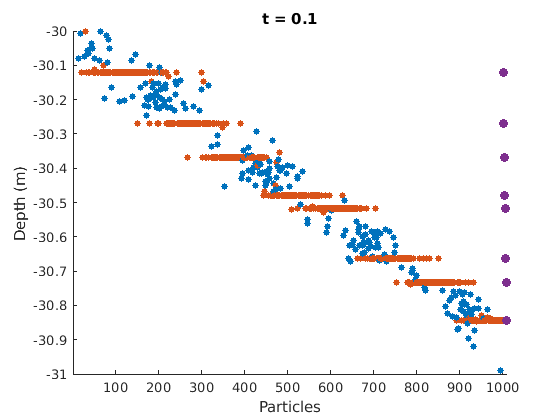



--------------------- Simulation running ---------------------
POUET
POUET
POUET
POUET
POUET
POUET
POUET
POUET
POUET
POUET
POUET


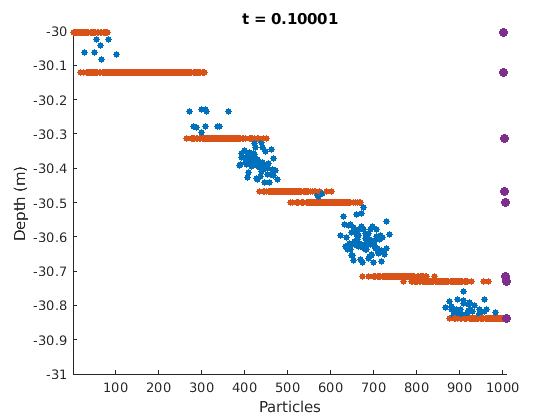

[collisionA, dtA] = Collision_Simulator(mp_list, agg_list, zInitMP, zInitAgg, K, dK, L, dz, tf, dt_test, dtB);


colTestA = cell2mat(collisionA');
DataColA = colTestA(:,1);

colTestB = cell2mat(collisionB');
DataColB = colTestB(:,1);

clear colTestA colTestB,

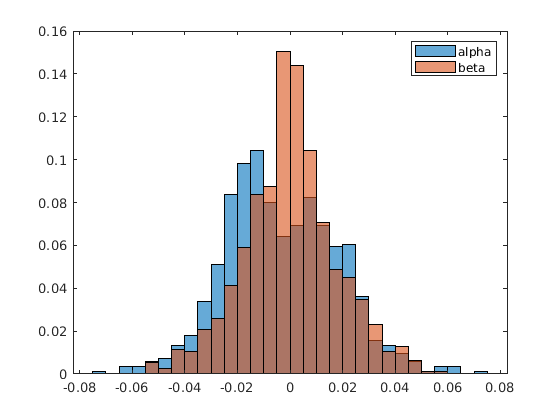

hA = histogram(DataColA,'Normalization','probability','BinWidth', 0.005, 'DisplayName','alpha');
hold on,
hB = histogram(DataColB,'Normalization','probability' ,'BinEdges',hA.BinEdges,'DisplayName','beta');
hold off,
legend

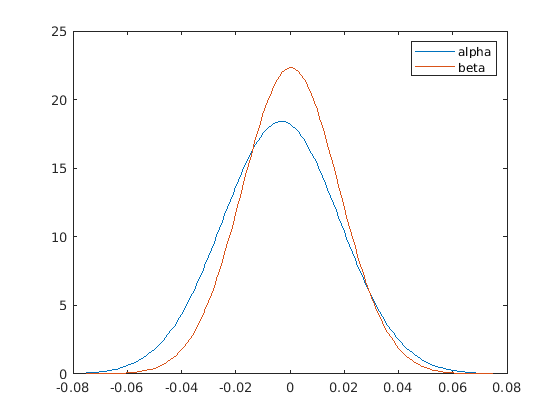


% pd = makedist('Normal',"mu",0,"sigma",std(DataCol));
% pdFit = fitdist(DataCol,'Kernel')
% % gaussienneTest = pdf(pd,h.BinEdges);
% gaussienneFit = pdf(pdFit,h.BinEdges);
% % plot(h.BinEdges,gaussienneTest)
% plot(h.BinEdges,gaussienneFit)
% hold off,
fitA = fitdist(DataColA,'Normal');
fitB = fitdist(DataColB,'Normal');
xfit = hA.BinLimits(1):1e-3:hA.BinLimits(2);
plot(xfit,pdf(fitA,xfit),'DisplayName','alpha')
hold on,
plot(xfit,pdf(fitB,xfit),'DisplayName','beta')
hold off,
% xline((mean(sizeAgg)+mean(sizeMP))/2)
legend